clc;clear all;close all;
clearvars
rng(100,'twister')
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
F:\onedrive\OneDrive - Imperial College London\PhD_Work\UQlab\UQLab_Rel2.0.0\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information





load('DATASET.mat');

 PROBABILISTIC INPUT MODEL for PCE

N_input = size(X,2)

N_input = 50

for i = 1: N_input
    InputOpts.Marginals(i).Type = 'Uniform';
    minX = min(X(:,i));
    maxX = max(X(:,i));
    InputOpts.Marginals(i).Parameters  = [minX maxX];
end
myInput = uq_createInput(InputOpts);

N_train = 900;
metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';

Select the LARS for the PCE coefficients calculation strategy:

Specify the sparse truncation scheme (hyperbolic norm with ):

metaopts.Method = 'LARS';
metaopts.TruncOptions.qNorm = 0.75;

Select the PCE options and create the PCE model:

metaopts.Degree = 2:15;

Experimental design (Note: PCE on Pricinple component of Y outputs, not on Y outputs)

X = X(1:N_train,:);
size(X)

ans =    900    50


Y = Y(1:N_train,:);
size(Y)

ans =    900    35


metaopts.ExpDesign.X = X;
metaopts.ExpDesign.Y = Y;
metaopts.ValidationSet.X = Xval;
metaopts.ValidationSet.Y = Yval;

Calculation

myPCE = uq_createModel(metaopts);

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 2 and qNorm 0.75 for output variable 1
Final LOO error estimate: 2.281830e-03
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 3 and qNorm 0.75 for output variable 2
Final LOO error estimate: 2.975180e-03
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 3 and qNorm 0.75 for output variable 3
Final LOO error estimate: 6.462347e-03
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 2 and qNorm 0.75 for output variab


YPCE= uq_evalModel(myPCE,Xval);

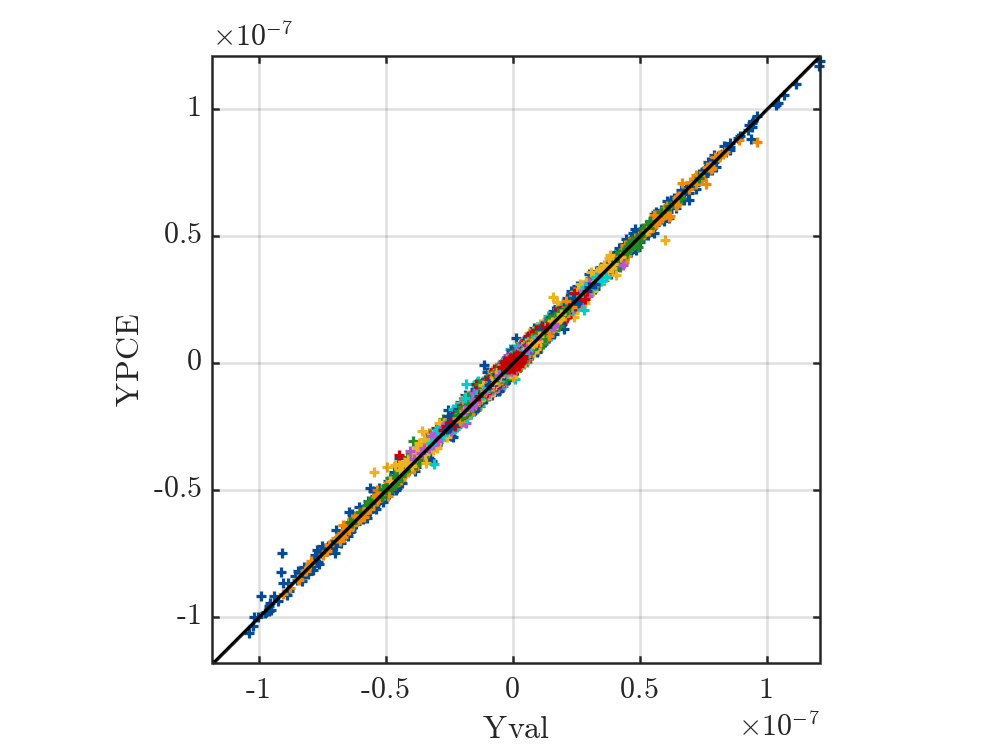

uq_figure
uq_plot(Yval, YPCE, '+')
hold on
uq_plot([min(Yval,[],'all') max(Yval,[],'all')], [min(Yval,[],'all') max(Yval,[],'all')], 'k')
hold off
axis equal
axis([min(Yval,[],'all') max(Yval,[],'all') min(Yval,[],'all') max(Yval,[],'all')])
xlabel('Yval');
ylabel('YPCE');
box on;

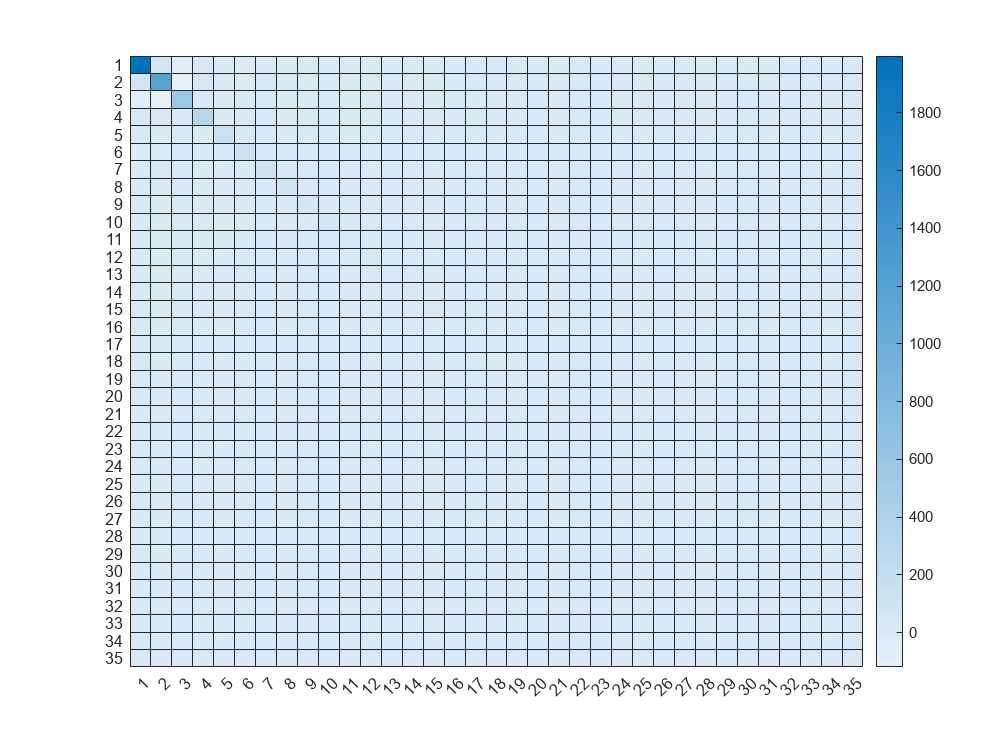

Output_FE_COV = cov(Yval./10^(-9));
heatmap(Output_FE_COV)

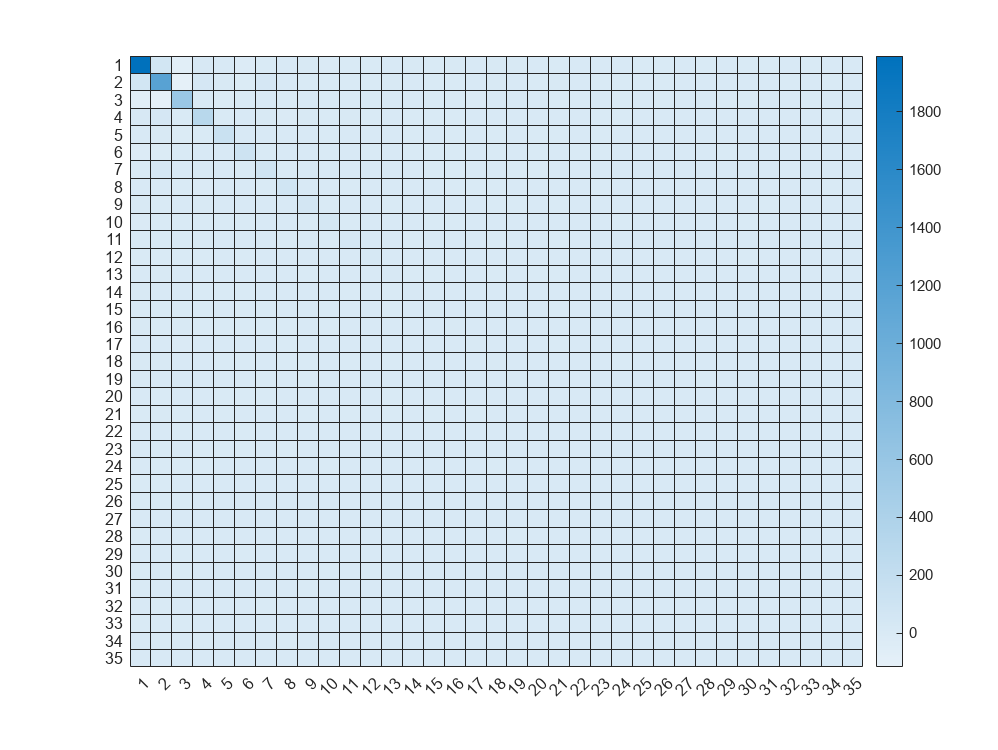



Output_PCE_COV = cov(YPCE./10^(-9));
heatmap(Output_PCE_COV)



Error = (Yval - YPCE)./10^(-9);
ErrorCov = cov(Error);
h = heatmap(ErrorCov)

h =   HeatmapChart - 属性:

        XData: {35×1 cell}
        YData: {35×1 cell}
    ColorData: [35×35 double]

  显示 所有属性


h.FontSize = 20

h =   HeatmapChart - 属性:

        XData: {35×1 cell}
        YData: {35×1 cell}
    ColorData: [35×35 double]

  显示 所有属性


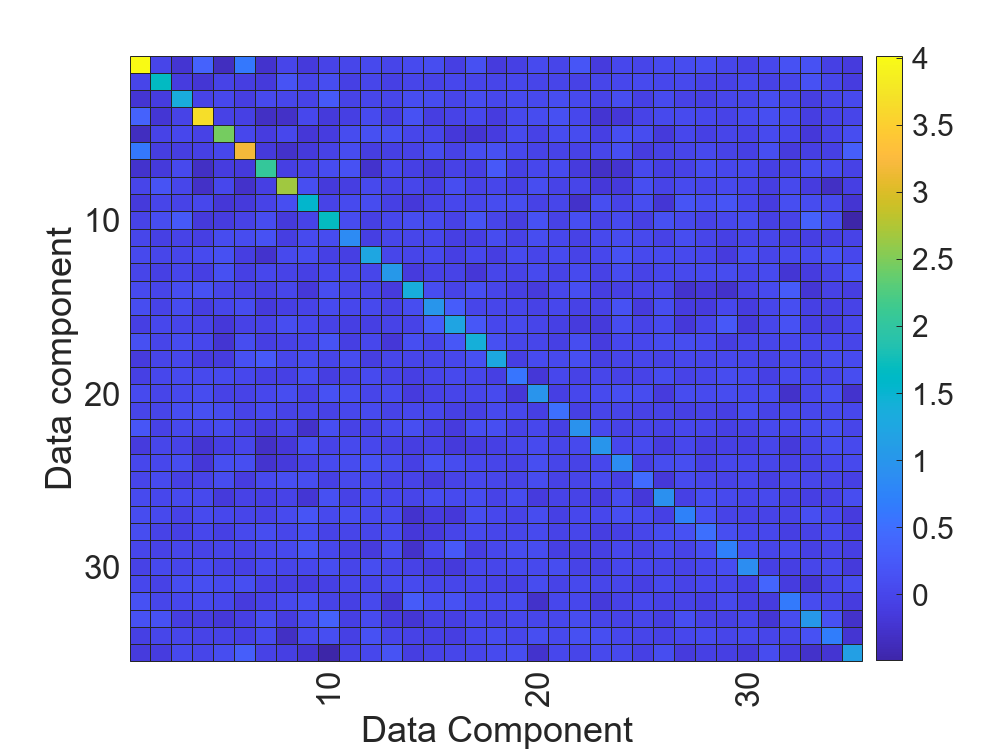

h =   HeatmapChart - 属性:

        XData: {35×1 cell}
        YData: {35×1 cell}
    ColorData: [35×35 double]

  显示 所有属性


xlabel('Data Component');
ylabel('Data component');
% original Xy label
xLabels = h.XDisplayLabels;
yLabels = h.YDisplayLabels;

% xticks for 10 20 30
xLabelsToShow = cell(size(xLabels));
yLabelsToShow = cell(size(yLabels));

for i = 1:length(xLabels)
    if ismember(str2num(xLabels{i}), [10, 20, 30])
        xLabelsToShow{i} = xLabels{i};
    else
        xLabelsToShow{i} = '';
    end
end

for j = 1:length(yLabels)
    if ismember(str2num(yLabels{j}), [10, 20, 30])
        yLabelsToShow{j} = yLabels{j};
    else
        yLabelsToShow{j} = '';
    end
end

% 设置 x 轴和 y 轴标签
h.XDisplayLabels = xLabelsToShow;
h.YDisplayLabels = yLabelsToShow;
 h.Colormap = parula